# The iterations of polygons under AFFINE IFS

### We consider the following planar affine IFS:

### 
$$S = \left\{ S_{k}=A_{k}x+t_{k} \right\}_{k=1}^{l}$$


### The initial polygon should be set priorly.

clc,clear
tic

# **Setting up**

**Warning: The *****cells***** of linear and translational parts should be of equal dimensions. **

**Arbitrary initial polygon could be set by its vertice.**

**Higher dimensions will cause the increase of computing time.**

Linearpart = {[0.25 0; 0 0.25], [0.25 0; 0 0.25], [0.25 0; 0 0.25], [0.25 0; 0 0.25], [0.5 0; 0 0.5]}; % the linar parts of the Affine IFS
Transpart = {[0; 0], [0.75; 0], [0.75; 0.75], [0; 0.75], [0.25; 0.25]}; % the translation parts of the Affine IFS
Initialshape = [0 1 1 0; 0 0 1 1]; % the vertices of the initial polygon

Iterationlevel = 6; % the level of iteration

## Check the compactibility of the settings

CompactibilityFlag = 0;
if length(Linearpart) == length(Transpart)
    CompactibilityFlag = 1;
end

if ~CompactibilityFlag
    error('Illegal settings. The dimensions of the parameter vectors should match!')
end

Num = length(Linearpart); % the number of fuctions in IFS if the settings are legal
[~, Shapesize] = size(Initialshape); % the dimension of the IFS the number of vertice of the initial shape

## Generate the vertice under iterations

Initialpoints = Initialshape; % the inital points for iteration
Currentpoints = Initialpoints; % the store the points at current level
Currentsize = Shapesize; % the size of the set of current points

Totalpoints = cell(1); % to store the points after each iteration
Totalpoints{1} = Initialpoints;

for Currentlevel = 1:Iterationlevel
    
    % Since we can not use the kronecker product directly due to the failure of
    % complex representing of the linear part, we have to do the
    % sub-iterations
    
    Temptpoints = []; % To store the temperate generated points after each subiteration
    for subiteration = 1:Num
        % Linear transformation
        AfterLinear = Linearpart{subiteration} * Currentpoints;
        
        % Translation
        TransVector = kron(Transpart{subiteration}, ones(1,Currentsize));
        
        % Store the generated points
        Temptpoints = [Temptpoints AfterLinear + TransVector];
    end
    
    % Renew the Currentpoints and Currentsize
    Currentpoints = Temptpoints;
    [~, Currentsize] = size(Currentpoints);
    
    Totalpoints = [Totalpoints; Currentpoints];
end

## Plot the iterated graph

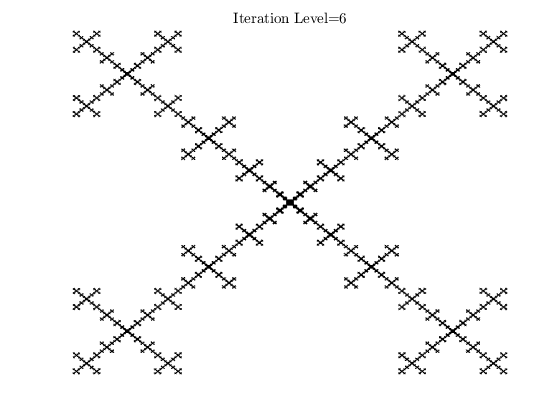

Xplotpts = reshape(Currentpoints(1,:), Shapesize, []); % reshape the x-coord for plotting
Yplotpts = reshape(Currentpoints(2,:), Shapesize, []); % reshape the y-coord for plotting

figure(1)
patch(Xplotpts,Yplotpts,'black')
set(gca,'XColor', 'none','YColor','none')
title(['Iteration Level=',num2str(Iterationlevel)], 'Interpreter', 'latex');

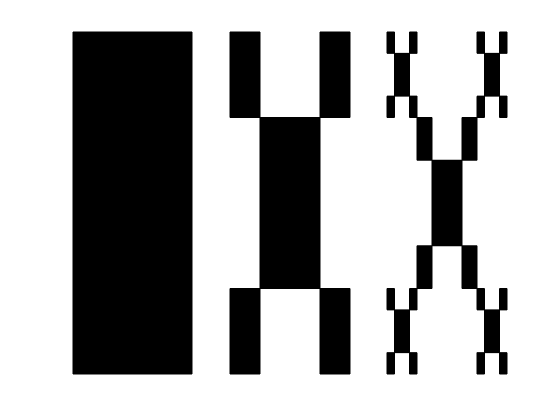


figure(2)
for plotposition = 1:3
    
    subplot(1,3,plotposition)
    Xsubplotpts = reshape(Totalpoints{plotposition}(1,:), Shapesize, []); % reshape the x-coord for plotting
    Ysubplotpts = reshape(Totalpoints{plotposition}(2,:), Shapesize, []); % reshape the y-coord for plotting
    patch(Xsubplotpts,Ysubplotpts,'black')
    set(gca,'XColor', 'none','YColor','none')
    % title(['Iteration Level=',num2str(plotposition-1)], 'Interpreter', 'latex');
    
end

## Output the other parameters

Num_Current_Points = Currentsize

Num_Current_Points = 62500

[~, Num_Current_Shapes] = size(Xplotpts)

Num_Current_Shapes = 15625